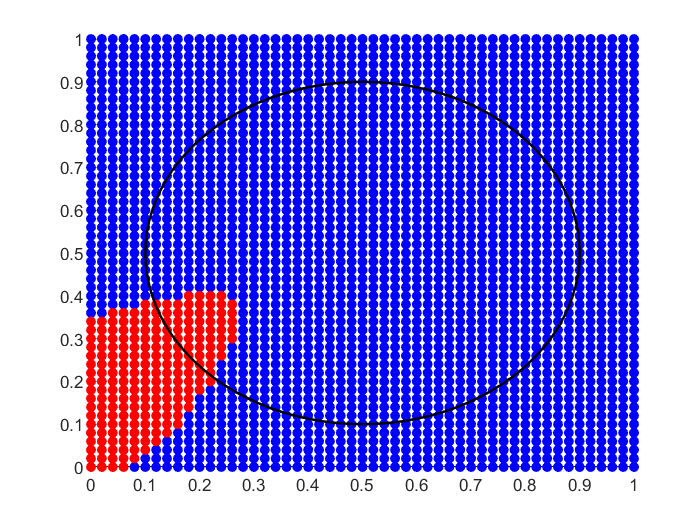

percentage_correct = 52.5567

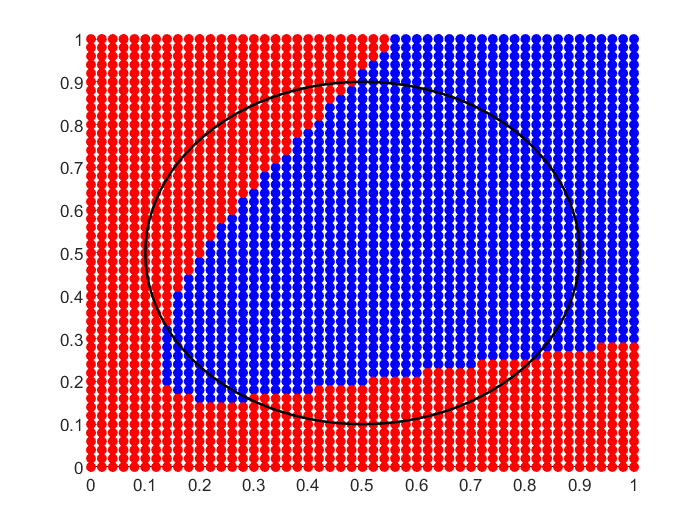

percentage_correct = 73.0873

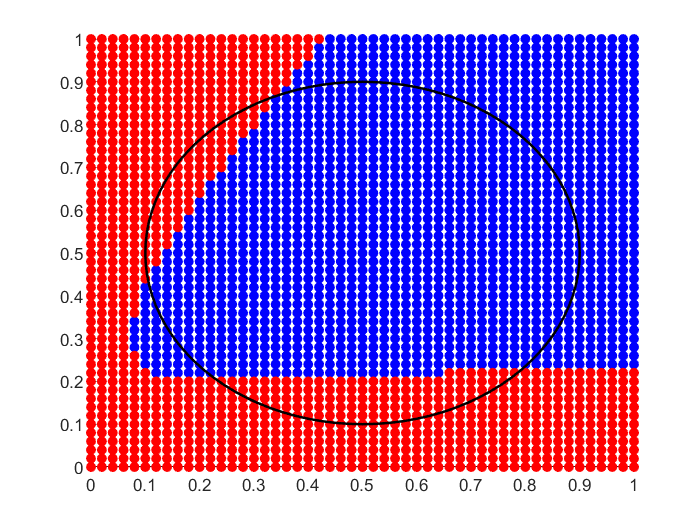

percentage_correct = 74.0869

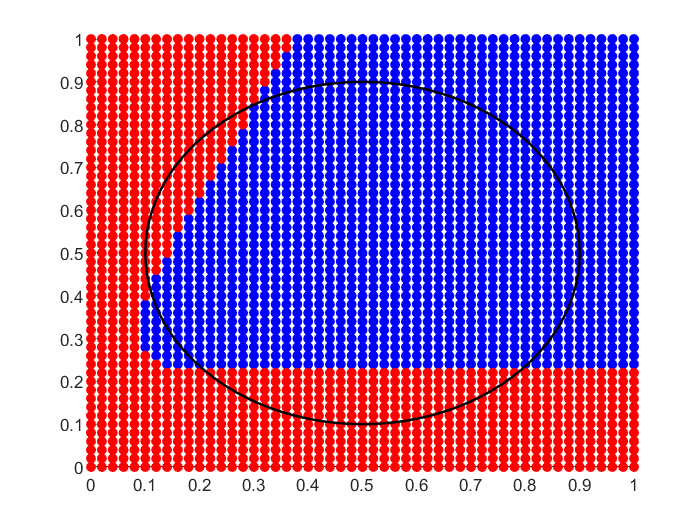

percentage_correct = 73.3180

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Cirkel");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_circle(grid);

% data to draw circle
th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;
    
% parameters
iterations = 10^4;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35];

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(xunit, yunit,'black','LineWidth',1.5);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Driehoek");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))]

data =     0.5750    0.4320    0.5770    0.5450    0.2860    0.3600    0.5050    0.3760    0.3630    0.3360    0.3130    0.3130    0.6590    0.2540    0.4610    0.6960    0.5260    0.4920    0.3540    0.5010    0.5240    0.5830    0.4110    0.5950    0.4870    0.5770    0.4420    0.3600    0.4510    0.4730    0.7330    0.4900    0.4060    0.4250    0.4920    0.5960    0.5540    0.4930    0.3190    0.4880    0.4850    0.2110    0.4380    0.7120    0.5590    0.4350    0.4130    0.5250    0.3860    0.5900
    0.3120    0.5260    0.5210    0.2680    0.3510    0.3040    0.7140    0.3490    0.4800    0.2610    0.2730    0.2060    0.2570    0.2630    0.4060    0.3430    0.6690    0.7460    0.4690    0.5700    0.2340    0.3910    0.3340    0.5550    0.5900    0.4980    0.3530    0.3880    0.6580    0.3640    0.3210    0.4730    0.3420    0.4300    0.2730    0.5870    0.6680    0.5050    0.3210    0.4400    0.2230    0.2020    0.4570    0.3130    0.3110    0.5810    0.2990    0.6810    0.2370  

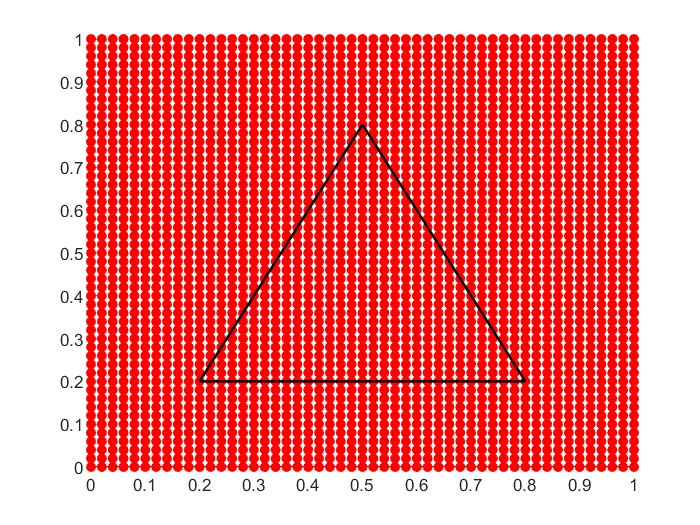

percentage_correct = 81.6993

percentage_correct = 81.6993

percentage_correct = 81.6993

percentage_correct = 81.6993


% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_triangle(grid);

xunit1 = linspace(0.2,0.8);
xunit2 = linspace(0.2,0.5);
xunit3 = linspace(0.5,0.8);
yunit1 = 0*xunit1 + 0.2;
yunit2 = 2*xunit2 - 0.2;
yunit3 = -2*xunit3 + 1.8;

% parameters
iterations = 10^4;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35];

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(xunit1, yunit1,'black','LineWidth',1.5);
    plot(xunit2, yunit2,'black','LineWidth',1.5);
    plot(xunit3, yunit3,'black','LineWidth',1.5);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Ster");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))]

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_circle(grid);

% parameters
iterations = 10^4;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35];

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end